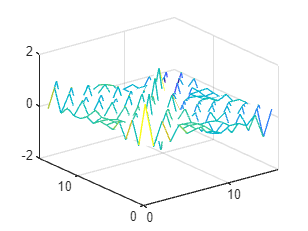

% We need the values of the integral of the greens function along with all
% its variables.
% assuming the equation ran at the boundary is 
% Fi x Iij = [mu*Pij - 2*pi*mu* U(xo)]
% the following is the arrangement of the grid elements around the boundary
    %     12 11 10 9
    %    13         8
    %    14         7
    %    15         6
    %    16         5
    %     1  2  3  4 
% here we will calculate the value of the entire G matrix, with the values
% of the all the i,j variations separate.

I_cell = cell(N_o_el);
% cell array to store the integral values of each index variation in a
% matrix

for n = 1:N_o_el
    xo = x_bound(n); yo = y_bound(n);
    % singular point co-ordinates
    for m = 1:N_o_el
        x = x_bound(m); y = y_bound(m);
        t_mat = zeros(2,2);
        % Matrix to save the index values
      
        for i = 1:2
            for j = 1:2
                if (m >= 1) && (m <= 0.25*N_o_el) % Lower boundary 
                    lim_1 = x + 2/N_o_el; %upper limit
                    lim_2 = x - 2/N_o_el; %lower limit
                    t_mat(i,j) = Grn_func_integration(x,xo,y,yo,i,j,1,lim_1,lim_2);
                end
                if (m >= 1 + 0.25*N_o_el) && (m <= 0.5*N_o_el) % Right boundary
                    lim_1 = y + 2/N_o_el; %upper limit
                    lim_2 = y - 2/N_o_el; %lower limit
                    t_mat(i,j) = Grn_func_integration(x,xo,y,yo,i,j,2,lim_1,lim_2);
                end
                if (m >= 1 + 0.5*N_o_el) && (m <= 0.75*N_o_el) % Top boundary
                    lim_1 = x - 2/N_o_el; %upper limit
                    lim_2 = x + 2/N_o_el; %lower limit
                    t_mat(i,j) = Grn_func_integration(x,xo,y,yo,i,j,1,lim_1,lim_2);
                end
                if(m >= 1 + 0.75*N_o_el) && (m <= N_o_el) % Left boundary
                    lim_1 = y - 2/N_o_el; %upper limit
                    lim_2 = y + 2/N_o_el; %lower limit
                    t_mat(i,j) = Grn_func_integration(x,xo,y,yo,i,j,2,lim_1,lim_2);
                end
            end
        end
        I_cell{n,m} = t_mat';
    end
end

I_mat = cell2mat(I_cell);
% converted the cell array N x N to a matrix of 2N x 2N elements
mesh(I_mat)